# Coursework - Control System

Student Name: ___________________

Student ID: ______________________

Note: 

- *Add proper comments where necessary inside the code area*

- *Add proper titles, legends, axes labels on your plots*

## Part a: State Space Model

Create a non-linear state space model, considering:

- *Use your system parameters to get the the state space model.*

- *Show complete steps on separate page*

clear;
clc;

% System parameters
m = 0.05;    % mass of the ball, kg
g = 9.8;    % the acceleration due to gravity, m/s^2
L = 0.01;    % inductance of the coil, H
R = 1;         % Resistance, ohms
K = 0.0001;     % coefficient that determines the magnetic force exerted on the ball
y_0 = 0.01;    % operating point, m

% state space matrix (type in your own matrix

A = [....;
    ...;
    ...]
B = [....]
C = [...]
D = 0;

% MATLAB command to create a state space model
state_space_model = ss(A, B, C, D)


## Part b: Transfer Function

Determine the transfer function of the system, controlling height ℎ of the suspended ball. Consider the linearized model given in the appendix.

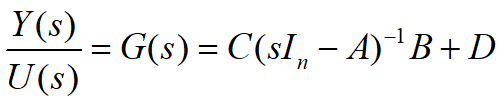

- *Show your calculation on the separate page for the transfer function*

MATLAB Commands: [`[b,a] = ss2tf(A,B,C,D)`](https://www.mathworks.com/help/matlab/ref/ss2tf.html#d126e1683158)

This will give you the numerator and denominator of the transfer function. use it to get the transfer function 

% Transfer function of the system
% commands to get the transfer function
[b,a] = ss2tf(A,B,C,D)
TF = tf(b, a) % transfer function

## Part c: Stability Analysis

Analyze the open loop response of the plant in terms of stability using MATLAB. Show necessary plots.

- *Discuss the stability depending upon the pole and their location*

- *If possible create routh's array on separate paper to discuss the stability*

MATLAB Commands: `eig(A)`

% Open loop step response 
% commands to get step response
p = eig(A)
pzmap(TF)

*Create the Simulink Model to verify the response.*

[Simulink Model for open-loop step response](matlab:open('./OpenLoopStepResponse.slx'))

## Part d: Controlability & Observability

Discuss observability and controllability using MATLAB.

State controllability

Output controllability

State Observability

- *use proper formulae for the calculation; verify your results with MATLAB commands*

MATLAB Commands:

- `ctrb(A,B)`

- `obsv(A,C)`

% Controllability
P = ctrb(A,B)
rank(ctrb(state_space_model))

% Observability
R = obsv(A,C)
rank(obsv(state_space_model))

## Part e: Full-state feedback controller

Design a state feedback controller (the reasonable design criteria specification is up to you). (MATLAB/SIMULINK).

*Determine the gain K*

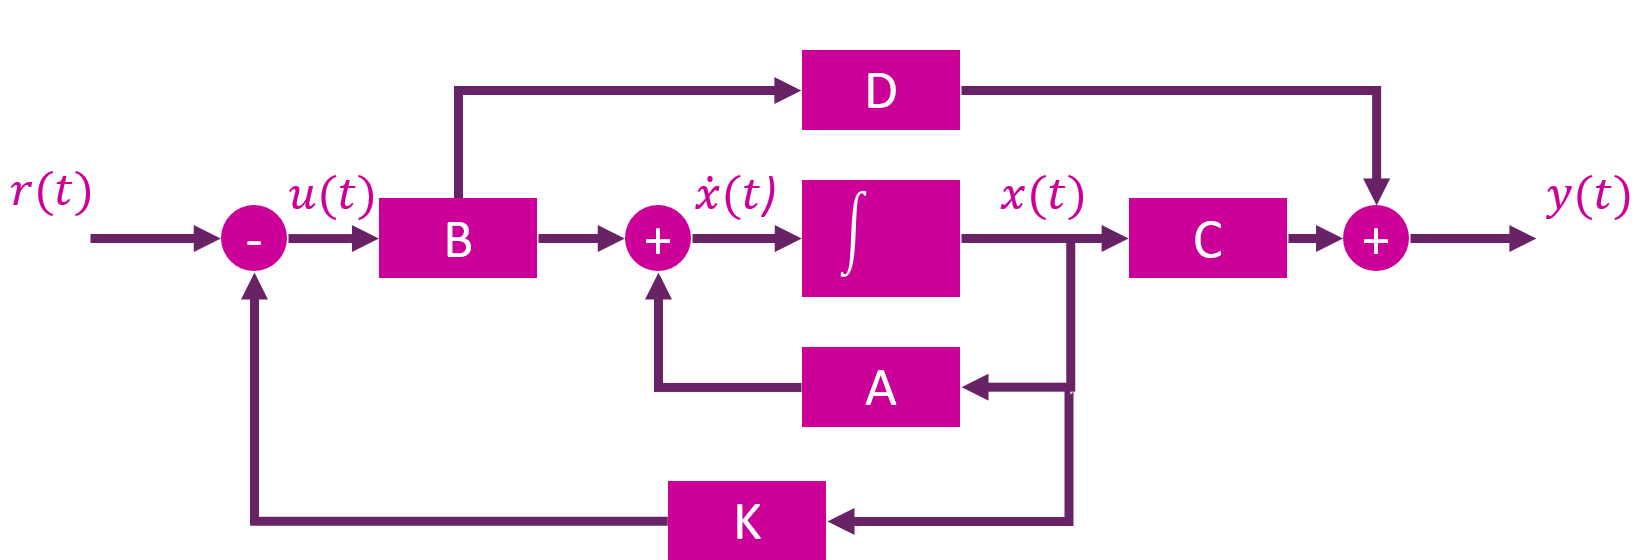

*Before attempting to design a state feedback controller, decide what are your goals. Set your goals as:*

- *Settling time, for example: ts < 0.5sec*

- *Overshoot, for example: Mp < 5%*

*Then decide where to place the poles. Poles are shown like *$s = \sigma + j\omega_d$, which can also be written as:

*So calculate *$\sigma$* and *$\omega_d$* accordingly.*

*Now determine the gain *$K$*using MATLAB command*, `K = place(A,B,[p1 p2 p3])`

*If possible solve for the gain *$K$* by following the method used in lecture. Attach your calculation on the separate page.*

***Example:***

- *calculate *$\zeta$ from the formula of the overshoot $M_p$

- calculate the $\sigma$ from settling time $t_s$

- calculate $\omega_d$ from $\sigma$

% considering zeta = 0.7 and sigma 10
% selecting poles as below:(type in your own poles)

p1 = ....;
p2 = ....;
p3 = ....;

% Determining gain K matrix using pole placement
K = place(A,B,[p1 p2 p3])

*Develop the Simulink Model to implement the Full State Feedback System using the gains calculated above*

[Full State Feedback Controller Simulink](matlab:open('./FullStateFeedbackControl.slx'))

*Note: If the overshoot is still large, place the poles further away to the left side of the s-plane, calculate the required parameters again.*

## Part f: Observer Design

Design a corresponding observer and explain when it will be used. (MATLAB/SIMULINK).

*Determine the gain *$K_e$

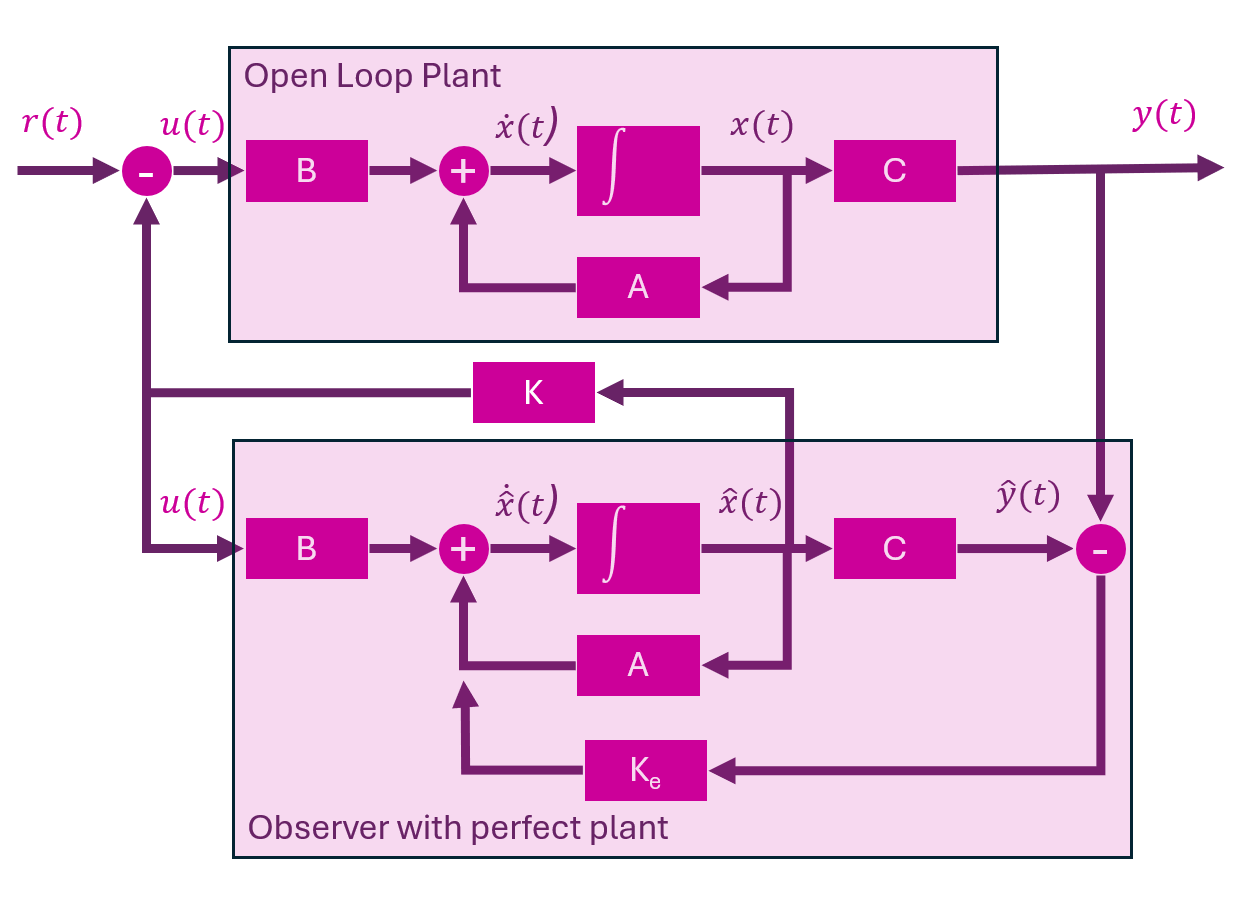

Since we want the dynamics of the observer to be much faster than the system itself, we need to place the poles at least five times farther to the left than the dominant poles of the system.

*Now determine the gain *$K_e$ *using MATLAB command*, `K = place(A',C',[p1 p2 p3])`

*If possible solve for the gain *$K$* by following the method used in lecture. Attach your calculation on the separate page.*

% choosen the poles further away to the left side in the s-plane
%(type in your own poles)
op1 = ...;
op2 = ...;
op3 = ...;

% determining the gain Ke
Ke = place(A',C',[op1 op2 op3])'

*Develop the Simulink Model to implement the Observer based System using the gains calculated above*

[Observer Based System -  Simulink](matlab:open('./ObserverDesignControl.slx'))

## Conclusion

## References